% Experiment Number 2
% Solution of Transcendental Equation using Simple Iteration Method
% Accuracy Based Stopping Criterion
% Programmer - Sahil Patra
% Roll No - 124MM0055

clc;
clear;

% Function definition
f = @(x) x.*log10(x) - 1.2;

% Rearranged form: x = g(x)
g = @(x) 1.2 ./ log10(x);

% Derivative of g(x) for convergence check
dg = @(x) abs(-1.2 ./ (x .* log(10) .* (log10(x).^2)));

% Inputs
a   = input('\nEnter Initial Guess (x > 0): ');
tol = input('Enter desired accuracy (e.g., 1e-6): ');
maxIter = 100;   % safety limit

% Domain check
if a <= 0
    error('Initial guess must be positive since log10(x) is undefined for x ≤ 0.');
end

% Convergence condition check for Simple Iteration
d = dg(a);
if d >= 1
    error('Simple Iteration Method may not converge for this initial guess.');
end

% Simple Iteration Process
c = a;
iter = 0;

while true
    iter = iter + 1;
    c_new = g(c);
    
    % Accuracy-based stopping criterion
    if abs(c_new - c) < tol
        c = c_new;
        break;
    end
    
    c = c_new;
    
    if iter >= maxIter
        warning('Maximum iterations reached without convergence.');
        break;
    end
end


% Results
fprintf('\nRoot ≈ %.8f\n', c);


Root ≈ 2.74036037


fprintf('Number of Iterations = %d\n', iter);

Number of Iterations = 100


fprintf('Final Error |f(x)| = %.8e\n', abs(f(c)));

Final Error |f(x)| = 2.49184415e-04



% Plotting
x1 = linspace(-10, 10, 100);
y  = f(x1);

figure;
plot(x1, y, 'r', 'LineWidth', 2); hold on;

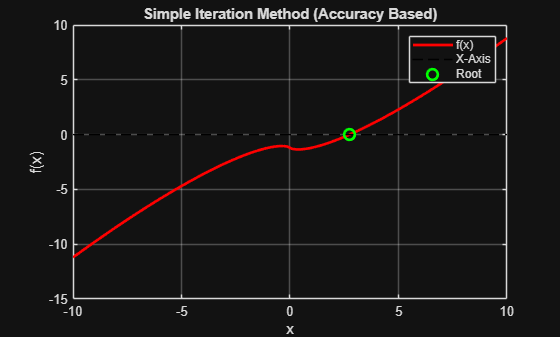

plot(x1, zeros(size(x1)), 'k--');
plot(c, f(c), 'go', 'MarkerSize', 8, 'LineWidth', 2);

xlabel('x');
ylabel('f(x)');
title('Simple Iteration Method (Accuracy Based)');
legend('f(x)', 'X-Axis', 'Root');
grid on;